Problem 15

clear
g = 9.81;
m = [0.6 0.4];
M = sum(m)

M = 1

(a) acceleration of the center of mass for the cart-block system

accel = m(2)/M*g

accel = 3.9240

a = [accel  0
     0      -accel]

a =     3.9240         0
         0   -3.9240


ac = a*m'/M     % acceleration of cm

ac =     2.3544
   -1.5696


(b) velocity of com

syms t real positive
vc = ac*t

$$vc = \left(\begin{array}{c} \frac{2943\,t}{1250}\\ -\frac{981\,t}{625} \end{array}\right)$$

(c) sketch the path taken by com

r0 = [-5    0
       0    -0.1]

r0 =    -5.0000         0
         0   -0.1000


rc0 = r0*m'/M

rc0 =    -3.0000
   -0.0400


rc = rc0 + 1/2*ac*t^2

$$rc = \left(\begin{array}{c} \frac{2943\,t^{2}}{2500}-3\\ -\frac{981\,t^{2}}{1250}-\frac{1}{25} \end{array}\right)$$

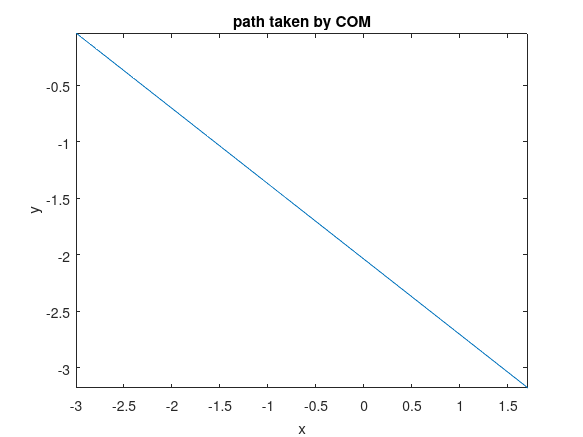

fplot(rc(1),rc(2),[0 2]), xlabel('x'), ylabel('y')
title('path taken by COM')

(d) Straight line

angle = atan2d(ac(2),ac(1))

angle = -33.6901